# Group Project

# Foundations of Computational Economics and Finance in MATLAB

## Read Data

clear
% readtable
T = [readtable('nswre74_treated.txt'); readtable('psid_controls.txt')];
% rename the variables (columns)
T.Properties.VariableNames = {'treatment' 'age' 'education' 'black' 'hispanic' 'married' 'nodegree' 'RE74' 'RE75' 'RE78'};
% display the first three rows
head(T, 3)

    treatment    age    education    black    hispanic    married    nodegree    RE74    RE75     RE78 
    _________    ___    _________    _____    ________    _______    ________    ____    ____    ______

        1        37        11          1         0           1          1         0       0        9930
        1        22         9          0         1           0          1         0       0      3595.9
        1        30        12          1         0           0          0         0       0       24909



## 4. Analysis of the Employment Program					

means, medians, and standard deviations , separated by program participants and non-participants 

### 4.1 Data Preparation

% T1 is a 780*7 table including observations for the 780 African Americans(black)
T1 = T(T.black == 1, {'treatment' 'age' 'education' 'married' 'nodegree' 'RE75' 'RE78'});
% groupwise summary statistics: create a table with the means, medians, and standard deviations
prep = grpstats(T1, 'treatment', {'mean'});
disp(cell2table(table2cell(prep)','RowNames',prep.Properties.VariableNames,'VariableNames',prep.Properties.RowNames))

                         0          1   
                      _______    _______

    treatment               0          1
    GroupCount            624        156
    mean_age           34.162     25.981
    mean_education     10.391     10.314
    mean_married      0.78846     0.1859
    mean_nodegree     0.53045    0.72436
    mean_RE75           13975     1490.7
    mean_RE78           15870     6136.3



prep = grpstats(T1, 'treatment', {'median'});
disp(cell2table(table2cell(prep)','RowNames',prep.Properties.VariableNames,'VariableNames',prep.Properties.RowNames))

                          0        1   
                        _____    ______

    treatment               0         1
    GroupCount            624       156
    median_age             32        25
    median_education       11        11
    median_married          1         0
    median_nodegree         1         1
    median_RE75         13427         0
    median_RE78         14777    3879.6



prep = grpstats(T1, 'treatment', {'std'});
disp(cell2table(table2cell(prep)','RowNames',prep.Properties.VariableNames,'VariableNames',prep.Properties.RowNames))

                        0          1   
                     _______    _______

    treatment              0          1
    GroupCount           624        156
    std_age           10.519     7.2996
    std_education     2.9827     2.0598
    std_married      0.40873    0.39028
    std_nodegree     0.49947    0.44828
    std_RE75          9169.8     3296.6
    std_RE78           11838     8143.5



### 4.2 Estimation procedure

#### 4.2.1 Algorithm for the estimation method

% The matrix X has dimension 780x6 (i.e. 780 rows and 6 columns). The first column contains a vec�tor of ones, and columns 2-6 are the independent variables age, education, married, nodegree, and RE75 
X = [table(ones(size(T1,1),1)),T1(:,{'age','education','married','nodegree','RE75'})];
X = table2array(X);
% y1 and y0 denote the target variable RE78 with observations for program participants and non-participants
y1 = T1.RE78(T1.treatment == 1);
y0 = T1.RE78(T1.treatment == 0);
% X1 and X0 are submatrices of X for program participants and non-participants, respectively
X1 = table2array([table(ones(size(y1,1),1)),T1(T1.treatment == 1,{'age' 'education' 'married' 'nodegree' 'RE75'})]);
X0 = table2array([table(ones(size(y0,1),1)),T1(T1.treatment == 0,{'age' 'education' 'married' 'nodegree' 'RE75'})]);
b1 = (X1' * X1)^-1 * X1' * y1;
b0 = (X0' * X0)^-1 * X0' * y0;
mu1 = X * b1;
mu0 = X * b0;
xita_hat = mean((mu1-mu0)'*(T1.treatment==1))

xita_hat = 1.9438e+05

#### 4.2.2 bootstrap standard error

% random seed
rng(123)
% Perform 199 bootstrap replications
B = 199;
N = 780;
xita_hat_boots = zeros(B, 1);
for i = 1:B
% the same as 4.2.1
    idx_boot = randi([1, N], N, 1);
    TB = T1(idx_boot,:);
    X = table2array([table(ones(size(TB,1),1)),TB(:,{'age' 'education' 'married' 'nodegree' 'RE75'})]);
    y1 = TB.RE78(TB.treatment == 1);
    y0 = TB.RE78(TB.treatment == 0);
    X1 = table2array([table(ones(size(y1,1),1)),TB(TB.treatment == 1,{'age' 'education' 'married' 'nodegree' 'RE75'})]);
    X0 = table2array([table(ones(size(y0,1),1)),TB(TB.treatment == 0,{'age' 'education' 'married' 'nodegree' 'RE75'})]);
    b1 = (X1' * X1)^-1 * X1' * y1;
    b0 = (X0' * X0)^-1 * X0' * y0;
    mu1 = X * b1;
    mu0 = X * b0;
    % store xita_hat_boots
    xita_hat_boots(i) = mean((mu1-mu0)'*(TB.treatment==1));
end
% calculate the standard error
bootstrp_xita = std(xita_hat_boots)

bootstrp_xita = 1.4584e+05

## 5  Evaluation of an Estimation Method through Data Simulations (Part 2)

### 5.1 Stimulation of data

% The new dataset T2 thus has 624 rows (individuals) and 7 columns (variables)
T2 = T1(T1.treatment == 0, {'age' 'education' 'married' 'nodegree' 'RE75' 'RE78'});
% calculate blogit
% the coefficients of a logit regression of the treatment variable used in Section 4 on X
X = table2array([table(ones(size(T1,1),1)),T1(:,{'age' 'education' 'married' 'nodegree' 'RE75'})]);
blogit = glmfit(X,T1.treatment,'binomial','Link','logit','Constant','off');
treatmentn = zeros(size(T1,1),1);
treatmentn(X * blogit > 0) = 1;
T2.treatment = treatmentn(T1.treatment == 0);
NN = 1000; 
Beta = zeros(NN,7); % OLS slope coefficient
boot_std = zeros(NN,7); % bootstrap standard error
tvalue = zeros(NN,7); % t statistics
pvalue = zeros(NN,7); % p value
H = zeros(NN,7); % if p value > 0.05, H = 0 
% start simulation
tic
M = 3;

parfor (i = 1:NN, M)

    simulated_data = simulated(T2);

    % generate the dependent variable RE78
    sim_ones = ones(size(T2,1),1);
    sim_age = simulated_data(:,1);
    sim_education = simulated_data(:,2);
    sim_married = table2array(T2(:,{'married'}));
    sim_nodegree = table2array(T2(:,{'nodegree'}));
    sim_RE75 = simulated_data(:,3);
    Xsim = table(sim_ones,sim_age,sim_education,sim_married,sim_nodegree,sim_RE75);
    u = normrnd(0,1,[624 1]);
    v = normrnd(0,1,[624 1]);
    N1 = size(X1,1);
    N0 = size(X0,1);
    K = size(Xsim,2)-1;
    miu1sim = table2array(Xsim)*b1+u*sqrt((N1-K)^(-1)*(X1*b1-y1)'*(X1*b1-y1));
    miu0sim = table2array(Xsim)*b0+u*sqrt((N0-K)^(-1)*(X0*b0-y0)'*(X0*b0-y0));
    % The simulated dependent variable RE78 is equal to µsim(1) (µsim(0)) if the simulated treatmentvariable is equal to 1 (0).
    sim_RE78 = miu0sim;
    sim_RE78(T2.treatment==1) = miu1sim(T2.treatment==1);

    % In each simulation, estimate the slope coefficients, standard errors, t-values, and p-values of the OLS model.
    X = [sim_ones,sim_age,sim_education,sim_married,sim_nodegree,sim_RE75,T2.treatment];
    y = sim_RE78;
    Beta(i,:) = (X'*X)^-1*X'*y; % OLS estimator
    [boot_std(i,:),tvalue(i,:),pvalue(i,:),H(i,:)] = boomstrap_std(X,y,624);

end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 4 workers.


toc

历时 82.442125 秒。


delete(gcp('nocreate'))

Parallel pool using the 'Processes' profile is shutting down.


### 5.2 OLS estimator

% create a table that shows the means of these four statistics across all simulations
table = array2table([mean(Beta);mean(boot_std);mean(tvalue);mean(pvalue)]);
table.Properties.VariableNames = {'intercept' 'age' 'education' 'married' 'nodegree' 'RE75' 'treatment'};
table.Properties.RowNames = {'coeffcients','standard errors','t-values','p-values'};
disp(table)

                       intercept       age       education     married     nodegree        RE75        treatment
                       _________    _________    _________    _________    _________    ___________    _________

    coeffcients           7868.1      -81.565     -114.65        2110.7      -2380.5        0.80505      1383.5 
    standard errors       3412.3       45.396      211.99        887.93       1262.2       0.045121      1713.3 
    t-values              32.791      -25.513     -7.6521        33.639      -26.671         253.02      11.526 
    p-values           0.0026642    0.0072429    0.031749     0.0025153    0.0080845    2.7855e-225    0.030621 



% calculate the proportion of simulations with p < 0.05 and interpret the result
porp = sum(H(:,7))/size(H,1);
disp(porp)

    0.9150



### Stimulation for participants

T3 = T1(T1.treatment == 1, {'age' 'education' 'married' 'nodegree' 'RE75' 'RE78'});
T3.treatment = treatmentn(T1.treatment == 1);

[G,married,nodegree,treatment] = findgroups(T3.married,T3.nodegree,T3.treatment);
% finding that group one only have 1 observation, we cant calculate its mu
% and sigma, so we choose to delete this observation, then we only have 155
T3 = T3(G~=1,:);
G = findgroups(T3.married,T3.nodegree,T3.treatment);

NN = 1000; 
Beta2 = zeros(NN,7); % OLS slope coefficient
boot_std2 = zeros(NN,7); % bootstrap standard error
tvalue2 = zeros(NN,7); % t statistics
pvalue2 = zeros(NN,7); % p value
H2 = zeros(NN,7); % if p value > 0.05, H = 0 

% start simulation
tic
M = 3;


parfor (m = 1:NN, M)
    mu = [];
    sigma = [];
    max_age = [];
    max_education = [];
    max_RE75 = [];
    min_age = [];
    min_education = [];
    min_RE75 = [];

    for i=1:6
        mu = [mu;mean([T2(G == i,:).age,T2(G == i,:).education,T2(G == i,:).RE75])];
        sigma = [sigma;cov([T2(G == i,:).age,T2(G == i,:).education,T2(G == i,:).RE75])];
        max_age = [max_age;max(T2(G == i,:).age)];
        max_education = [max_education;max(T2(G == i,:).education)];
        max_RE75 = [max_RE75;max(T2(G == i,:).RE75)];
        min_age = [min_age;min(T2(G == i,:).age)];
        min_education = [min_education;min(T2(G == i,:).education)];
        min_RE75 = [min_RE75;min(T2(G == i,:).RE75)];
    end

    simulated_data = zeros(size(T3,1),3);
    j = 1;
    while j <= size(T3,1)
        g = G(j);
        R = mvnrnd(mu(g,:),sigma(3*g-2:3*g,:),1);
        R(1) = round(R(1)); 
        R(2) = round(R(2)); 
        if R(1)<=max_age(g) && R(1)>=min_age(g) ... 
            && R(2)<=max_education(g) && R(2)>=min_education(g) ... 
            && R(3)<=max_RE75(g) && R(3)>=min_RE75(g) 
            simulated_data(j,:) = R;
            j = j+1;
        end
    end

    % generate the dependent variable RE78
    sim_ones = ones(size(T3,1),1);
    sim_age = simulated_data(:,1);
    sim_education = simulated_data(:,2);
    sim_married = table2array(T3(:,{'married'}));
    sim_nodegree = table2array(T3(:,{'nodegree'}));
    sim_RE75 = simulated_data(:,3);
    Xsim = [sim_ones,sim_age,sim_education,sim_married,sim_nodegree,sim_RE75];
    u = normrnd(0,1,[155 1]);
    v = normrnd(0,1,[155 1]);
    N1 = size(X1,1);
    N0 = size(X0,1);
    K = size(Xsim,2)-1;
    miu1sim = Xsim*b1+u*sqrt((N1-K)^(-1)*(X1*b1-y1)'*(X1*b1-y1));
    miu0sim = Xsim*b0+u*sqrt((N0-K)^(-1)*(X0*b0-y0)'*(X0*b0-y0));
    % The simulated dependent variable RE78 is equal to µsim(1) (µsim(0)) if the simulated treatmentvariable is equal to 1 (0).
    sim_RE78 = miu0sim;
    sim_RE78(T3.treatment==1) = miu1sim(T3.treatment==1);
    % In each simulation, estimate the slope coefficients, standard errors, t-values, and p-values of the OLS model.
    
    X = [sim_ones,sim_age,sim_education,sim_married,sim_nodegree,sim_RE75,T3.treatment];
    y = sim_RE78;
    Beta2(m,:) = (X'*X)^-1*X'*y; % OLS estimator
    [boot_std2(m,:),tvalue2(m,:),pvalue2(m,:),H2(m,:)] = boomstrap_std(X,y,155);
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 4 workers.


delete(gcp('nocreate'))

Parallel pool using the 'Processes' profile is shutting down.


% create a table that shows the means of these four statistics across all simulations
table = array2table([mean(Beta2);mean(boot_std2);mean(tvalue2);mean(pvalue2)]);
table.Properties.VariableNames = {'intercept' 'age' 'education' 'married' 'nodegree' 'RE75' 'treatment'};
table.Properties.RowNames = {'coeffcients','standard errors','t-values','p-values'};
disp(table)

                       intercept      age       education    married     nodegree      RE75      treatment 
                       _________    ________    _________    ________    ________    ________    __________

    coeffcients           11139      -16.633      287.04       869.84     -1819.9     0.14107       -8483.7
    standard errors       10940       118.49      798.41       2418.5      1563.4     0.13002        2598.7
    t-values             14.588      -1.8703      5.1317       5.2581     -16.577      14.855       -47.048
    p-values           0.028172     0.042946    0.047012     0.037902    0.017795    0.033583    0.00052286



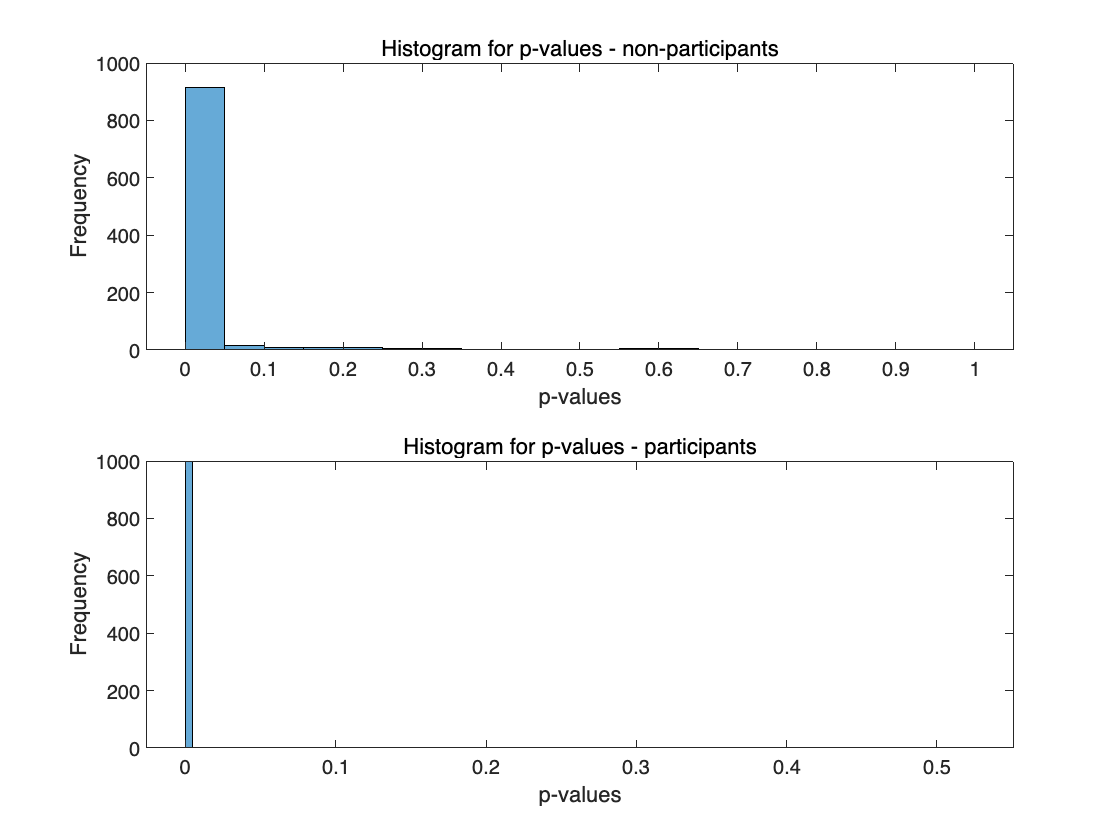

subplot(2,1,1);
ax = gca;  
histogram(pvalue(:,7))
ax.XLabel.String = 'p-values'; 
ax.YLabel.String = 'Frequency';
title('Histogram for p-values - non-participants')
subplot(2,1,2); 
ax = gca;  
histogram(pvalue2(:,7))
ax.XLabel.String = 'p-values'; 
ax.YLabel.String = 'Frequency';
title('Histogram for p-values - participants')

## Task Distribution

- **XinyueMeng: **4(Analysis of the Employment Program (Part 1)), part of 5.1(Simulation of data)

- **Jue Yan: **5(Evaluation of an Estimation Method through Data Simulations)

- **SiyuanXue****: **participation in group discussion, improvement of the efficiency of the code